clear;
clc

x = iris_dataset;
y = [zeros(1,50),ones(1,50)];
x1 = x(1,1:100);
min(x1)

ans = 4.3000

max(x1)

ans = 7

j=1

j = 1

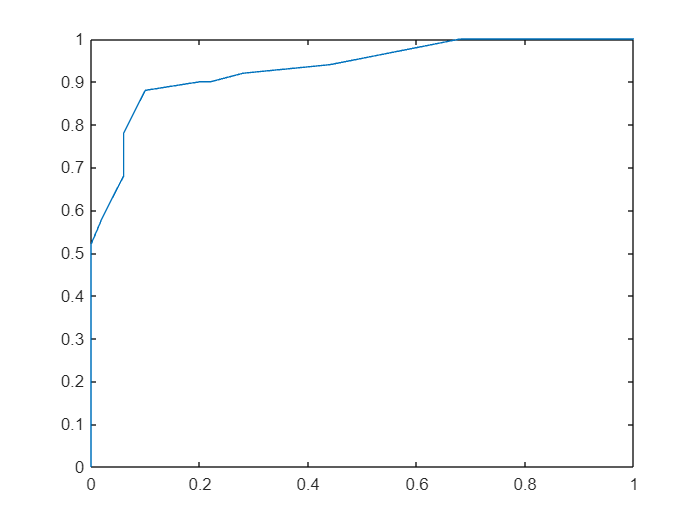

for i = 7 : -0.05: 4
    Tp = sum(x1(51:100)>i == y(51:100));
    Fn = 50-Tp;
    Tn = sum(x1(1:50)>i == y(1:50));
    Fp = 50 - Tn;
    Tpr(j) = Tp/(Tp+Fn);
    Fpr(j) = Fp/(Fp+Tn);
    j = j +1;
end


plot(Fpr,Tpr)